
clear;

% --- Symbolic Derivation of Swashplate Kinematics ---
% This script derives the positions of points p_i based on points q_i
% and geometric constraints.
%
% Key variables:
%   s_i: Servo base positions (calculated based on r and servo angles)
%   n_i: Unit normal vectors for servo planes (derived from s_i)
%   q_i: Servo horn tip positions (calculated based on s_i, r_s, theta_i)
%   p_i: Swashplate connection points
%
% Constraints for p_i:
%   1. Distance |p_i - q_i| = r_p (pitch link length)
%   2. Points p_i lie on a circle of radius r_w
%   3. This circle is centered at (0, 0, z_c) in a plane z = z_c.
%
% CRITICAL POINT: z_c is treated as a SYMBOLIC VARIABLE in this derivation.
% The resulting expressions for p_i will be functions of z_c.
% Conditions for the existence of real solutions for p_i will also be
% derived as inequalities involving z_c.

% --- Define Symbolic Variables ---
clearvars; % Clear existing variables to ensure a clean run
syms theta_1 theta_2 theta_3 real % Servo input angles
syms r r_s real                   % r: servo placement radius, r_s: servo horn length
syms r_p real                     % r_p: length of the pitch link
syms r_w real                     % r_w: radius of the swashplate circle (p-points)
syms z_c real                     % z_c: z-coordinate of the swashplate circle (VARIABLE)

% Assumptions for simplification (can be removed if r, r_s, etc. can be non-positive)
assume(r > 0);
assume(r_s > 0);
assume(r_p > 0);
assume(r_w > 0);

theta_vec = [theta_1, theta_2, theta_3]; % Vector of theta angles

% --- Calculate Servo Base Positions (s_i) ---
fprintf('1. Calculating symbolic servo base positions (s_i)...\n');

1. Calculating symbolic servo base positions (s_i)...


s = sym(zeros(3,3));
gamma_angle = 2*pi/3; % Servo spacing
servo_mount_angles = [0, gamma_angle, 2*gamma_angle];

for i = 1:3
    angle_i = servo_mount_angles(i);
    s(:,i) = [r*cos(angle_i); r*sin(angle_i); 0]; % s_i are in z=0 plane
end
disp('Symbolic s matrix (columns are s1, s2, s3):');

Symbolic s matrix (columns are s1, s2, s3):


disp(s);

$$\left(\begin{array}{ccc} r & -\frac{r}{2} & -\frac{r}{2}\\ 0 & \frac{\sqrt{3}\,r}{2} & -\frac{\sqrt{3}\,r}{2}\\ 0 & 0 & 0 \end{array}\right)$$


% --- Calculate Servo Plane Unit Normal Vectors (n_i) ---
fprintf('\n1b. Calculating symbolic servo plane unit normal vectors (n_i)...\n');


1b. Calculating symbolic servo plane unit normal vectors (n_i)...


n_unit = sym(zeros(3,3)); % Unit vectors in direction of s_i (since s_i_z=0 and servos rotate in XY plane relative to s_i)
for i = 1:3
    n_unit(:,i) = s(:,i)/r; % Since norm(s(:,i)) = r and s_i are in xy plane.
end
n = simplify(n_unit); % Assign to 'n' as expected by plotting script
disp('Symbolic n matrix (unit normal vectors for servo planes):');

Symbolic n matrix (unit normal vectors for servo planes):


disp(n);

$$\left(\begin{array}{ccc} 1 & -\frac{1}{2} & -\frac{1}{2}\\ 0 & \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{2}\\ 0 & 0 & 0 \end{array}\right)$$



% --- Calculate Servo Horn Tip Positions (q_i) ---
fprintf('\n2. Calculating symbolic servo horn tip positions (q_i)...\n');


2. Calculating symbolic servo horn tip positions (q_i)...


% Basis vectors for servo horn motion (relative to s_i)
% u_i: Tangential vector in the servo plane (orthogonal to n_i and in XY plane)
% v_i: Axial vector (along the servo rotation axis, here global Z if n_i is in XY)

u_basis = [-n(2,:);  % u_i is tangent to the circle of servo bases, using n
            n(1,:);
            zeros(1,3)];
u_basis = simplify(u_basis ./ sqrt(sum(u_basis.^2,1))); % Normalize u_basis

v_basis = cross(n, u_basis, 1); % v_i should be [0;0;1] for each servo if n is in XY plane
v_basis = simplify(v_basis);

% Delta vectors (displacement from s_i to q_i)
delta_q = sym(zeros(3,3));
for i = 1:3
    delta_q(:,i) = u_basis(:,i) * r_s * cos(theta_vec(i)) + ...
                   v_basis(:,i) * r_s * sin(theta_vec(i));
end
delta_q = simplify(delta_q);

q_calculated = s + delta_q;
q_calculated = simplify(q_calculated);
disp('Symbolic q matrix (columns are q1, q2, q3, functions of theta_i):');

Symbolic q matrix (columns are q1, q2, q3, functions of theta_i):


disp(q_calculated);

$$\begin{array}{l} \left(\begin{array}{ccc} r & -\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & \frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}-\frac{r}{2}\\ r_{s}\,\cos\left(\theta_{1}\right) & \sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & -\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2} \end{array}$$


% --- Derive p_i from q_i (p_i are functions of z_c) ---
fprintf('\n3. Deriving symbolic expressions for p_i (functions of z_c and theta_i)...\n');


3. Deriving symbolic expressions for p_i (functions of z_c and theta_i)...


% Each p_i = [p_ix; p_iy; z_c]
% There are two potential solutions for (p_ix, p_iy) for each p_i.

p_solutions_set1 = sym(zeros(3,3)); % For one choice of sqrt sign
p_solutions_set2 = sym(zeros(3,3)); % For the other choice of sqrt sign
conditions_for_zc = cell(3,1);      % Store symbolic inequalities for z_c
D_sq_expressions_zc = cell(3,1);    % To store symbolic D_sq_i(z_c)

for i = 1:3
    fprintf('   For point p_%d (derived from q_%d, using theta_%d):\n', i, i, i);
    
    x_qi = q_calculated(1,i);
    y_qi = q_calculated(2,i);
    z_qi = q_calculated(3,i); % This is r_s * sin(theta_vec(i))
    
    rho_sq_i = simplify(x_qi^2 + y_qi^2); 
    fprintf('     rho_%d_sq (x_qi^2+y_qi^2) = %s\n', i, char(rho_sq_i));
    
    K_i_zc = r_w^2 + rho_sq_i + (z_c - z_qi)^2 - r_p^2;
    K_i_zc = simplify(K_i_zc);
    fprintf('     K_%d(z_c) = %s\n', i, char(K_i_zc));
    
    D_sq_i_zc = 4*r_w^2*rho_sq_i - K_i_zc^2;
    D_sq_i_zc = simplify(D_sq_i_zc);
    D_sq_expressions_zc{i} = D_sq_i_zc; % Store for output to workspace
    fprintf('     D_sq_%d(z_c) (discriminant term) = %s\n', i, char(D_sq_i_zc));
    
    condition_i = (D_sq_i_zc >= 0);
    conditions_for_zc{i} = condition_i;
    fprintf('     Condition for real p_%d (from D_sq_%d(z_c) >= 0): %s\n', i, i, char(condition_i));

    den_i = 2*rho_sq_i;
    sqrt_D_sq_i_zc = sqrt(D_sq_i_zc); 
    
    p_xi_sol1 = simplify((x_qi * K_i_zc + y_qi * sqrt_D_sq_i_zc) / den_i);
    p_yi_sol1 = simplify((y_qi * K_i_zc - x_qi * sqrt_D_sq_i_zc) / den_i);
    p_solutions_set1(:,i) = [p_xi_sol1; p_yi_sol1; z_c]; 
    
    p_xi_sol2 = simplify((x_qi * K_i_zc - y_qi * sqrt_D_sq_i_zc) / den_i);
    p_yi_sol2 = simplify((y_qi * K_i_zc + x_qi * sqrt_D_sq_i_zc) / den_i);
    p_solutions_set2(:,i) = [p_xi_sol2; p_yi_sol2; z_c]; 
end

   For point p_1 (derived from q_1, using theta_1):


     rho_1_sq (x_qi^2+y_qi^2) = r_s^2*cos(theta_1)^2 + r^2


     K_1(z_c) = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)


     D_sq_1(z_c) (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2


     Condition for real p_1 (from D_sq_1(z_c) >= 0): 0 <= 4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2


   For point p_2 (derived from q_2, using theta_2):


     rho_2_sq (x_qi^2+y_qi^2) = r_s^2*cos(theta_2)^2 + r^2


     K_2(z_c) = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)


     D_sq_2(z_c) (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2


     Condition for real p_2 (from D_sq_2(z_c) >= 0): 0 <= 4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2


   For point p_3 (derived from q_3, using theta_3):


     rho_3_sq (x_qi^2+y_qi^2) = r_s^2*cos(theta_3)^2 + r^2


     K_3(z_c) = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)


     D_sq_3(z_c) (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2


     Condition for real p_3 (from D_sq_3(z_c) >= 0): 0 <= 4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2



fprintf('\n4. Symbolic expressions for p_i (functions of z_c, theta_i, and constants):\n');


4. Symbolic expressions for p_i (functions of z_c, theta_i, and constants):


disp('p_solutions_set1 (columns are [p1_x;p1_y;z_c], [p2_x;p2_y;z_c], [p3_x;p3_y;z_c]):');

p_solutions_set1 (columns are [p1_x;p1_y;z_c], [p2_x;p2_y;z_c], [p3_x;p3_y;z_c]):


disp(p_solutions_set1);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{r\,\sigma_{13}+r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{10}}{\sigma_{3}} & -\frac{\sigma_{7}\,\sigma_{12}-\sigma_{5}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{6}\,\sigma_{11}+\sigma_{4}\,\sigma_{8}}{\sigma_{1}}\\ -\frac{r\,\sigma_{10}-r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{13}}{\sigma_{3}} & \frac{\sigma_{5}\,\sigma_{12}+\sigma_{7}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{4}\,\sigma_{11}-\sigma_{6}\,\sigma_{8}}{\sigma_{1}}\\ z_{c} & z_{c} & z_{c} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\\ \sigma_{2}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\\ \sigma_{3}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{4}=\frac{\sqrt{3}\,r}{2}+\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{3}\,r}{2}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{6}=\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{7}=\frac{r}{2}+\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{8}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)-{\sigma_{11}}^{2}}\\ \sigma_{9}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)-{\sigma_{12}}^{2}}\\ \sigma_{10}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\right)-{\sigma_{13}}^{2}}\\ \sigma_{11}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{3}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{12}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{2}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{13}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{1}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2} \end{array}$$

disp('p_solutions_set2 (columns are [p1_x;p1_y;z_c], [p2_x;p2_y;z_c], [p3_x;p3_y;z_c]):');

p_solutions_set2 (columns are [p1_x;p1_y;z_c], [p2_x;p2_y;z_c], [p3_x;p3_y;z_c]):


disp(p_solutions_set2);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{r\,\sigma_{13}-r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{10}}{\sigma_{3}} & -\frac{\sigma_{7}\,\sigma_{12}+\sigma_{5}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{6}\,\sigma_{11}-\sigma_{4}\,\sigma_{8}}{\sigma_{1}}\\ \frac{r\,\sigma_{10}+r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{13}}{\sigma_{3}} & \frac{\sigma_{5}\,\sigma_{12}-\sigma_{7}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{4}\,\sigma_{11}+\sigma_{6}\,\sigma_{8}}{\sigma_{1}}\\ z_{c} & z_{c} & z_{c} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\\ \sigma_{2}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\\ \sigma_{3}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{4}=\frac{\sqrt{3}\,r}{2}+\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{3}\,r}{2}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{6}=\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{7}=\frac{r}{2}+\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{8}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)-{\sigma_{11}}^{2}}\\ \sigma_{9}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)-{\sigma_{12}}^{2}}\\ \sigma_{10}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\right)-{\sigma_{13}}^{2}}\\ \sigma_{11}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{3}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{12}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{2}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{13}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{1}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2} \end{array}$$


fprintf('\n5. Symbolic discriminant expressions D_sq_i(z_c) (stored in D_sq_expressions_zc):\n');


5. Symbolic discriminant expressions D_sq_i(z_c) (stored in D_sq_expressions_zc):


for i = 1:3
    fprintf('   D_sq_%d(z_c) = %s\n', i, char(D_sq_expressions_zc{i}));
end

   D_sq_1(z_c) = 4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2
   D_sq_2(z_c) = 4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2
   D_sq_3(z_c) = 4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2



fprintf('\n6. Conditions that z_c must satisfy for real solutions:\n');


6. Conditions that z_c must satisfy for real solutions:


for i = 1:3
    fprintf('   For p_%d: %s\n', i, char(conditions_for_zc{i}));
end

   For p_1: 0 <= 4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2
   For p_2: 0 <= 4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2
   For p_3: 0 <= 4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2



fprintf('\n--- Explanation for Determining z_c ---\n');


--- Explanation for Determining z_c ---


fprintf('The variable z_c is the z-coordinate of the plane containing the p_i points.\n');

The variable z_c is the z-coordinate of the plane containing the p_i points.


fprintf('The derivations above provide p_i as functions of this z_c.\n');

The derivations above provide p_i as functions of this z_c.


fprintf('For a physically valid solution:\n');

For a physically valid solution:


fprintf('  1. z_c must be a real number.\n');

  1. z_c must be a real number.


fprintf('  2. For each point p_i, its corresponding condition D_sq_i(z_c) >= 0 must be met.\n');

  2. For each point p_i, its corresponding condition D_sq_i(z_c) >= 0 must be met.


fprintf('     This means z_c must lie in the intersection of the solution sets for these three inequalities:\n');

     This means z_c must lie in the intersection of the solution sets for these three inequalities:


fprintf('       S_total = {z_c | D_sq_1(z_c)>=0 AND D_sq_2(z_c)>=0 AND D_sq_3(z_c)>=0}\n');

       S_total = {z_c | D_sq_1(z_c)>=0 AND D_sq_2(z_c)>=0 AND D_sq_3(z_c)>=0}


fprintf('  3. If S_total is empty, no such z_c exists for the given input parameters.\n');

  3. If S_total is empty, no such z_c exists for the given input parameters.


fprintf('  4. The plotting script attempts to find such a z_c numerically.\n');

  4. The plotting script attempts to find such a z_c numerically.



fprintf('\nSymbolic script finished. Variables are in the workspace.\n');


Symbolic script finished. Variables are in the workspace.


fprintf('Ensure you run this script before the plotting script.\n');

Ensure you run this script before the plotting script.


fprintf('The following key variables should now be in your workspace:\n');

The following key variables should now be in your workspace:


fprintf('s, n, q_calculated, p_solutions_set1, p_solutions_set2, D_sq_expressions_zc,\n');

s, n, q_calculated, p_solutions_set1, p_solutions_set2, D_sq_expressions_zc,


fprintf('and the symbolic parameters: r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c\n');

and the symbolic parameters: r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c


bro idk anymore

% --- MATLAB Plotting Script for Swashplate Kinematics (Solves for zc) ---
%
% IMPORTANT PREREQUISITE:
% The main symbolic derivation script (e.g., "matlab_robotics_kinematics_corrected.m")
% MUST be run successfully BEFORE this plotting script. That script will create
% necessary symbolic variables and expressions in the MATLAB workspace, including:
%   - s, n, q_calculated (symbolic matrices for servo base, normals, horn tips)
%   - p_solutions_set1, p_solutions_set2 (symbolic solutions for p_i)
%   - D_sq_expressions_zc (CELL ARRAY of symbolic discriminant expressions D_sq_i(z_c))
%   - Symbolic variables: r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c

fprintf('Starting plotting script...\n');

Starting plotting script...



% --- Check for prerequisite variables from the symbolic script ---
required_vars_from_symbolic_script = {'s', 'n', 'q_calculated', ...
                                      'p_solutions_set1', 'p_solutions_set2', ...
                                      'D_sq_expressions_zc', ...
                                      'r', 'r_s', 'theta_1', 'theta_2', 'theta_3', ...
                                      'r_p', 'r_w', 'z_c'};
missing_vars = {};
for i_var_check = 1:length(required_vars_from_symbolic_script)
    if ~exist(required_vars_from_symbolic_script{i_var_check}, 'var')
        missing_vars{end+1} = required_vars_from_symbolic_script{i_var_check};
    end
end

if ~isempty(missing_vars)
    error_msg = sprintf(['Missing required variable(s) from the symbolic script: %s. ' ...
                       'Please ensure the main symbolic derivation script ' ...
                       '(e.g., "matlab_robotics_kinematics_corrected.m") ' ...
                       'has been run successfully in the current MATLAB session before this plotting script.'], ...
                       strjoin(missing_vars, ', '));
    error(error_msg);
end

fprintf('All required symbolic variables found in workspace.\n');

All required symbolic variables found in workspace.



% --- Define Numerical Parameters ---
r_value = 1.0;        % Servo placement radius
rs_value = 0.5;     % Servo horn length
theta_input_values = [0; 0; 0]; % Example servo angles (theta_1, theta_2, theta_3)

% Parameters for p points (swashplate and links)
rp_value = 1.2;     % Length of pitch links (distance |q_i - p_i|)
rw_value = 0.8;     % Radius of the swashplate circle (circle of points p)

fprintf('Using input parameter values:\n');

Using input parameter values:


fprintf('r (servo placement radius): %f\n', r_value);

r (servo placement radius): 1.000000


fprintf('rs (servo horn length): %f\n', rs_value);

rs (servo horn length): 0.500000


fprintf('theta_1, theta_2, theta_3: %f, %f, %f (radians)\n', theta_input_values(1), theta_input_values(2), theta_input_values(3));

theta_1, theta_2, theta_3: 0.000000, 0.000000, 0.000000 (radians)


fprintf('rp (pitch link length): %f\n', rp_value);

rp (pitch link length): 1.200000


fprintf('rw (swashplate radius): %f\n', rw_value);

rw (swashplate radius): 0.800000



% --- Calculate local_q (numerical servo horn tip positions) ---
local_q = double(subs(q_calculated, ...
                     [r, r_s, theta_1, theta_2, theta_3], ...
                     [r_value, rs_value, theta_input_values(1), theta_input_values(2), theta_input_values(3)]));

% --- Solve for z_c ---
fprintf('\nSolving for z_c...\n');


Solving for z_c...



% Numerical values for parameters to substitute into D_sq expressions
% Note: z_c remains symbolic during this substitution for D_sq_numeric_in_zc
params_for_Dsq = {r, r_s, theta_1, theta_2, theta_3, r_p, r_w};
num_values_for_Dsq = {r_value, rs_value, theta_input_values(1), theta_input_values(2), theta_input_values(3), rp_value, rw_value};

% Substitute known numerical values into the symbolic D_sq expressions, leaving z_c symbolic
D_sq_numeric_in_zc = cell(3,1);
for k_idx = 1:3
    % D_sq_expressions_zc{k_idx} is the symbolic D_sq_i(z_c, r, r_s, theta_i, r_p, r_w)
    D_sq_numeric_in_zc{k_idx} = subs(D_sq_expressions_zc{k_idx}, params_for_Dsq, num_values_for_Dsq);
end

% Define search range for z_c
z_q_coords = local_q(3,:);
z_q_min = min(z_q_coords);
z_q_max = max(z_q_coords); % For reference

% Search range for z_c: aiming for z_c < z_q_min.
search_z_min = z_q_min - rp_value - 0.5; % Search a bit below z_q_min - rp_value
search_z_max = z_q_min - 1e-4; % Search up to just below z_q_min (ensuring strictly less)
num_zc_test_points = 2000; % Number of points to test for z_c
zc_test_values = linspace(search_z_min, search_z_max, num_zc_test_points);

valid_zc_candidates = [];
discriminant_tol = -1e-9; % Tolerance for D_sq >= 0 (allowing for small numerical errors)

for zc_val_test = zc_test_values
    % Substitute the test value of z_c into the D_sq expressions (which are now only functions of z_c)
    D1_val = double(subs(D_sq_numeric_in_zc{1}, z_c, zc_val_test));
    D2_val = double(subs(D_sq_numeric_in_zc{2}, z_c, zc_val_test));
    D3_val = double(subs(D_sq_numeric_in_zc{3}, z_c, zc_val_test));
    
    if D1_val >= discriminant_tol && D2_val >= discriminant_tol && D3_val >= discriminant_tol
        valid_zc_candidates(end+1) = zc_val_test;
    end
end

chosen_zc_value = NaN;
if ~isempty(valid_zc_candidates)
    chosen_zc_value = max(valid_zc_candidates); % Choose the highest valid z_c that is < z_q_min
    fprintf('Found valid z_c = %f (satisfies D_sq_i >= 0 and z_c < min(q_z)).\n', chosen_zc_value);
else
    fprintf('WARNING: Could not find a z_c that satisfies all D_sq_i >= 0 AND is strictly less than min(q_z) in the initial search range.\n');
    fprintf('Attempting a broader search for any valid z_c (may not be below q_z)...\n');
    
    search_z_min_broad = z_q_min - rp_value - 1.0; % Broader range min
    search_z_max_broad = z_q_max + rp_value + 1.0; % Broader range max, can be above q_z
    zc_test_values_broad = linspace(search_z_min_broad, search_z_max_broad, num_zc_test_points * 2);
    all_valid_zc_any_condition = [];
    
    for zc_val_test = zc_test_values_broad
        D1_val = double(subs(D_sq_numeric_in_zc{1}, z_c, zc_val_test));
        D2_val = double(subs(D_sq_numeric_in_zc{2}, z_c, zc_val_test));
        D3_val = double(subs(D_sq_numeric_in_zc{3}, z_c, zc_val_test));
        if D1_val >= discriminant_tol && D2_val >= discriminant_tol && D3_val >= discriminant_tol
            all_valid_zc_any_condition(end+1) = zc_val_test;
        end
    end
    
    if ~isempty(all_valid_zc_any_condition)
        % Prefer solutions below z_q_min if any exist in this broader search
        candidates_below_q_min = all_valid_zc_any_condition(all_valid_zc_any_condition < z_q_min);
        if ~isempty(candidates_below_q_min)
            chosen_zc_value = max(candidates_below_q_min);
            fprintf('Found z_c = %f from broader search (satisfies D_sq_i >= 0 and z_c < min(q_z)).\n', chosen_zc_value);
        else
            % If still none below, take the minimum of all valid z_c as a fallback (swashplate might be above some q_i)
            chosen_zc_value = min(all_valid_zc_any_condition); 
            fprintf('Selected z_c = %f (satisfies D_sq_i >= 0, but may not be < min(q_z)). Swashplate might be high or between q_z values.\n', chosen_zc_value);
        end
    else
        fprintf('CRITICAL WARNING: No z_c found that satisfies all D_sq_i >= 0 even in a broad search. Kinematics likely impossible for these parameters.\n');
        % chosen_zc_value remains NaN
    end
end

Found valid z_c = -0.000100 (satisfies D_sq_i >= 0 and z_c < min(q_z)).



if isnan(chosen_zc_value)
    fprintf('Cannot proceed with plotting p points as no valid z_c was determined.\n');
else
    fprintf('Using chosen z_c = %f for plotting p.\n', chosen_zc_value);
end

Using chosen z_c = -0.000100 for plotting p.


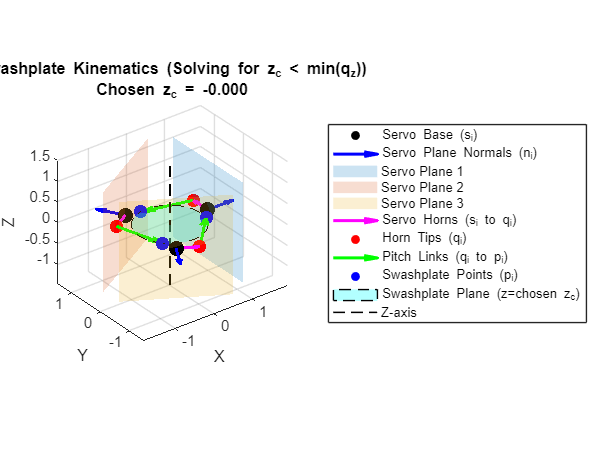


% --- Substitute for p (swashplate connection points) using chosen_zc_value ---
if ~isnan(chosen_zc_value)
    local_p = double(subs(p_solutions_set2, ... % Using set 2 as per previous preference
                         [r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c], ...
                         [r_value, rs_value, theta_input_values(1), theta_input_values(2), theta_input_values(3), rp_value, rw_value, chosen_zc_value]));
else
    local_p = nan(3,3); % Set p to NaN if no z_c found
end

% --- Plotting Setup ---
figureHandle = figure;
hold on;
axis equal;
view(3);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
titleStr = sprintf('Swashplate Kinematics (Solving for z_c < min(q_z))');
if ~isnan(chosen_zc_value)
    titleStr = [titleStr, sprintf('\nChosen z_c = %.3f', chosen_zc_value)];
else
    titleStr = [titleStr, '\nNo valid z_c found for p!'];
end
title(titleStr);

% --- Plot Servo Base (s) and Normals (n) ---
% Substitute for s and n (servo base and normals)
local_s = double(subs(s, r, r_value)); % s is only function of r
local_n = double(subs(n, r, r_value)); % n is only function of r

scatter3(local_s(1,:), local_s(2,:), local_s(3,:), 100, 'k', 'filled', 'DisplayName', 'Servo Base (s_i)');
quiver3(local_s(1,:), local_s(2,:), local_s(3,:), ...
        local_n(1,:), local_n(2,:), local_n(3,:), ...
        0.5, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Servo Plane Normals (n_i)');

% --- Plot Servo Planes ---
plot_colors = lines(3);
L_servo_plane = 1.2 * r_value;
plane_handles = gobjects(3,1);
for i_plane = 1:3
    ni_vec = local_n(:,i_plane);
    si_vec = local_s(:,i_plane);
    if abs(ni_vec(1)) < 1e-6 && abs(ni_vec(2)) < 1e-6 % Normal is along z-axis
        Bi_servo_plane = [1 0; 0 1; 0 0]; % Basis for XY plane
        if ni_vec(3) < 0; Bi_servo_plane(:,2) = -Bi_servo_plane(:,2); end % Correct orientation
    else
        Bi_servo_plane = null(ni_vec'); % 3x2 basis for the plane
    end
    corners_servo = [ ...
        si_vec + L_servo_plane*Bi_servo_plane(:,1) + L_servo_plane*Bi_servo_plane(:,2), ...
        si_vec + L_servo_plane*Bi_servo_plane(:,1) - L_servo_plane*Bi_servo_plane(:,2), ...
        si_vec - L_servo_plane*Bi_servo_plane(:,1) - L_servo_plane*Bi_servo_plane(:,2), ...
        si_vec - L_servo_plane*Bi_servo_plane(:,1) + L_servo_plane*Bi_servo_plane(:,2)  ...
    ]';
    plane_handles(i_plane) = patch('Vertices', corners_servo, 'Faces', [1 2 3 4], ...
          'FaceColor', plot_colors(i_plane,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
          'DisplayName', sprintf('Servo Plane %d', i_plane));
end

% --- Plot Servo Horns (s_i to q_i) and Horn Tips (q_i) ---
delta_q_s = local_q - local_s;
quiver3(local_s(1,:), local_s(2,:), local_s(3,:), ...
        delta_q_s(1,:), delta_q_s(2,:), delta_q_s(3,:), ...
        0, 'm', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Servo Horns (s_i to q_i)');
scatter3(local_q(1,:), local_q(2,:), local_q(3,:), 80, 'r', 'filled', 'DisplayName', 'Horn Tips (q_i)');

% --- Plot Pitch Links (q_i to p_i) and Swashplate Points (p_i) if z_c found ---
if ~isnan(chosen_zc_value) && ~any(isnan(local_p(:)))
    delta_p_q = local_p - local_q;
    quiver3(local_q(1,:), local_q(2,:), local_q(3,:), ...
            delta_p_q(1,:), delta_p_q(2,:), delta_p_q(3,:), ...
            0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Pitch Links (q_i to p_i)');
    scatter3(local_p(1,:), local_p(2,:), local_p(3,:), 80, 'b', 'filled', 'DisplayName', 'Swashplate Points (p_i)');

    % --- Plot the Plane of p_i (Swashplate Plane) ---
    phi_swash_plane = linspace(0, 2*pi, 100);
    x_swash_plane = rw_value * cos(phi_swash_plane);
    y_swash_plane = rw_value * sin(phi_swash_plane);
    z_swash_plane = chosen_zc_value * ones(size(phi_swash_plane));
    patch(x_swash_plane, y_swash_plane, z_swash_plane, 'c', ...
          'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineStyle', '--', ...
          'DisplayName', 'Swashplate Plane (z=chosen z_c)');
else
     fprintf('Skipping plot of p points and swashplate plane as z_c or p is invalid.\n');
end

% --- Plot the Z-axis ---
current_zlim_val = zlim(gca); 
all_z_points_for_lim = [local_s(3,:), local_q(3,:)];
if ~any(isnan(local_p(:))); all_z_points_for_lim = [all_z_points_for_lim, local_p(3,:)]; end
if ~isnan(chosen_zc_value); all_z_points_for_lim = [all_z_points_for_lim, chosen_zc_value]; end

plot_z_min = min([-0.5, all_z_points_for_lim, current_zlim_val(1)]);
plot_z_max = max([1.5, all_z_points_for_lim, current_zlim_val(2)]);
if ~isnan(chosen_zc_value) 
    plot_z_min = min(plot_z_min, chosen_zc_value - rw_value);
    plot_z_max = max(plot_z_max, chosen_zc_value + rw_value);
end
if plot_z_max <= plot_z_min; plot_z_max = plot_z_min + 1.0; end % Ensure valid range if all points are coplanar

plot3([0 0], [0 0], [plot_z_min plot_z_max], 'k--', 'LineWidth', 1, 'DisplayName', 'Z-axis');
zlim([plot_z_min plot_z_max]); 

% --- Labels & Legend ---
legend('Location','eastoutside');
hold off;
rotate3d on;


fprintf('\nPlotting script execution finished.\n');


Plotting script execution finished.


if isnan(chosen_zc_value)
    fprintf('FINAL STATUS: Could not determine a valid z_c for the swashplate.\n');
elseif any(isnan(local_p(:))) || any(~isreal(local_p(:))) && ~isnan(chosen_zc_value)
    fprintf('FINAL STATUS: chosen_zc_value = %f, but resulting p_i coordinates are NaN or complex.\n', chosen_zc_value);
    fprintf('This usually means D_sq_i was numerically negative for the chosen z_c, despite search. Check tolerance or search parameters.\n');
end


